% Extraction of Watermark
clear all;
N = 16;
M = 32*N;
key = 7;

%% UNCORRELATED PSEUDO RANDOM SEQUENCE GENERATOR

G=key;
%Generation of first m-sequence using generator polynomial [45]
sd1 =[0 0 0 0 1];             % Initial state of Shift register
PN1=[];                       % First m-sequence
for j=1:G
    PN1=[PN1 sd1(5)];
    if sd1(1)==sd1(4)
        temp1=0;
    else temp1=1;
    end
    sd1(1)=sd1(2);
    sd1(2)=sd1(3);
    sd1(3)=sd1(4);
    sd1(4)=sd1(5);
    sd1(5)=temp1;
end
sd2 =[0 0 0 0 1];             % Initial state of Shift register
PN2=[];                       % Second m-sequence
for j=1:G
    PN2=[PN2 sd2(5)];
    if sd2(1)==sd2(2)
        temp1=0;
    else temp1=1;
    end
    if sd2(4)==temp1
        temp2=0;
    else temp2=1;
    end
    if sd2(5)==temp2
        temp3=0;
    else temp3=1;
    end
    sd2(1)=sd2(2);
    sd2(2)=sd2(3);
    sd2(3)=sd2(4);
    sd2(4)=sd2(5);
    sd2(5)=temp3;
end

[signal, Fs] = audioread('Watermarked_out.wav');
x1 = signal(1:M^2);
x1 = reshape(x1,1,M^2);
x = reshape(x1, M, M);

[L,H,V,D]=dwt2(x,'haar','sym');
[H1,H2,H3,H4]=dwt2(H,'haar','sym');
[A1,A2,A3,A4]=dwt2(H2,'haar','sym');
[B1,B2,B3,B4]=dwt2(H3,'haar','sym');
[V1,V2,V3,V4]=dwt2(V,'haar','sym');
[C1,C2,C3,C4]=dwt2(V2,'haar','sym');
[D1,D2,D3,D4]=dwt2(V3,'haar','sym');

a = 4 + zeros(1,16);
b = 4 + zeros(1,16);
[L1, L2] = size(A2);
d=zeros(L1,L2);

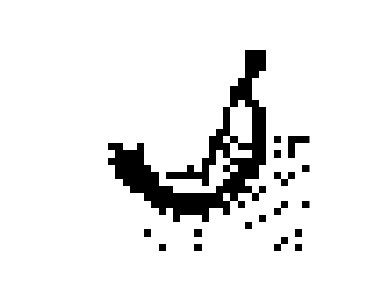

% DCT of sub-band A2
n_A2=mat2cell(A2,a,b);
nA2=mat2cell(d,a,b);
for i=1:16
    for j=1:16
        nA2{i,j}=dct2(n_A2{i,j});
    end
end

%% EXTRACTION OF WATERMARK BIT BY COMPARISON OF CORRELATION

for p=1:16
    for q=1:16
        if corr([nA2{p,q}(1,3) nA2{p,q}(1,4) nA2{p,q}(2,2) nA2{p,q}(2,3) nA2{p,q}(3,1) nA2{p,q}(3,2) nA2{p,q}(4,1)]',PN1(1:7)')>=corr([nA2{p,q}(1,3) nA2{p,q}(1,4) nA2{p,q}(2,2) nA2{p,q}(2,3) nA2{p,q}(3,1) nA2{p,q}(3,2) nA2{p,q}(4,1)]',PN2(1:7)')
            w2(p,q)=0;
        else
            w2(p,q)=1;
        end
    end
end

% DCT of sub-band B2
n_B2=mat2cell(B2,a,b);
nB2=mat2cell(d,a,b);
for i=1:16
    for j=1:16
        nB2{i,j}=dct2(n_B2{i,j});
    end
end
%% EXTRACTION OF WATERMARK BIT BY COMPARISON OF CORRELATION

for p=1:16
    for q=1:16
        if corr([nB2{p,q}(1,3) nB2{p,q}(1,4) nB2{p,q}(2,2) nB2{p,q}(2,3) nB2{p,q}(3,1) nB2{p,q}(3,2) nB2{p,q}(4,1)]',PN1(1:7)')>=corr([nB2{p,q}(1,3) nB2{p,q}(1,4) nB2{p,q}(2,2) nB2{p,q}(2,3) nB2{p,q}(3,1) nB2{p,q}(3,2) nB2{p,q}(4,1)]',PN2(1:7)')
            w2(p,q+16)=0;
        else
            w2(p,q+16)=1;
        end
    end
end

% DCT of sub-band C2
n_C2=mat2cell(C2,a,b);
d=zeros(64,64);
nC2=mat2cell(d,a,b);
for i=1:16
    for j=1:16
        nC2{i,j}=dct2(n_C2{i,j});
    end
end
%% EXTRACTION OF WATERMARK BIT BY COMPARISON OF CORRELATION

for p=1:16
    for q=1:16
        if corr([nC2{p,q}(1,3) nC2{p,q}(1,4) nC2{p,q}(2,2) nC2{p,q}(2,3) nC2{p,q}(3,1) nC2{p,q}(3,2) nC2{p,q}(4,1)]',PN1(1:7)')>=corr([nC2{p,q}(1,3) nC2{p,q}(1,4) nC2{p,q}(2,2) nC2{p,q}(2,3) nC2{p,q}(3,1) nC2{p,q}(3,2) nC2{p,q}(4,1)]',PN2(1:7)')
            w2(p+16,q)=0;
        else
            w2(p+16,q)=1;
        end
    end
end

% DCT of sub-band D2
n_D2=mat2cell(D2,a,b);
nD2=mat2cell(d,a,b);
for i=1:16
    for j=1:16
        nD2{i,j}=dct2(n_D2{i,j});
    end
end
%% EXTRACTION OF WATERMARK BIT BY COMPARISON OF CORRELATION

for p=1:16
    for q=1:16
        if corr([nD2{p,q}(1,3) nD2{p,q}(1,4) nD2{p,q}(2,2) nD2{p,q}(2,3) nD2{p,q}(3,1) nD2{p,q}(3,2) nD2{p,q}(4,1)]',PN1(1:7)')>=corr([nD2{p,q}(1,3) nD2{p,q}(1,4) nD2{p,q}(2,2) nD2{p,q}(2,3) nD2{p,q}(3,1) nD2{p,q}(3,2) nD2{p,q}(4,1)]',PN2(1:7)')
            w2(p+16,q+16)=0;
        else
            w2(p+16,q+16)=1;
        end
    end
end
sbr=w2;
figure
imshow(logical(w2))


%% Quality check
q=max(imabsdiff(x1,reshape(x,1,512*512)))

q = 0

% Reading the image to be embedded
img = imread('CW32.jpg');
% Binarize the image
gray_img = rgb2gray(img);
original_img = imbinarize(gray_img);
BER=biterr(original_img,sbr)

BER = 231

ssimval = ssim(uint8(sbr),uint8(original_img))

ssimval = 0.9893

ps=psnr(uint8(original_img),uint8(sbr)) % Must be greater than 35 dB

ps = 54.5977

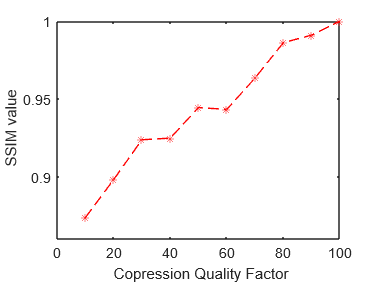

ssimValues = zeros(1,10);
qualityFactor = 10:10:100;
for i = 1:10
    imwrite(gray_img,'sbr.jpg','jpg','quality',qualityFactor(i));
    ssimValues(i) = ssim(imread('sbr.jpg'),gray_img);
end
figure
plot(qualityFactor,ssimValues,'r--*')
xlabel(' Copression Quality Factor');
ylabel(' SSIM value');